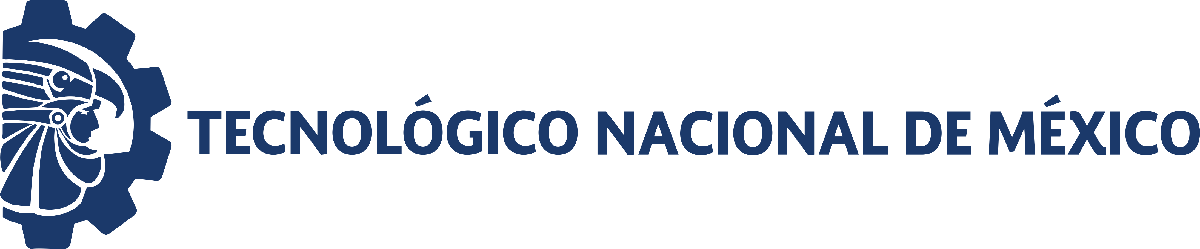                                 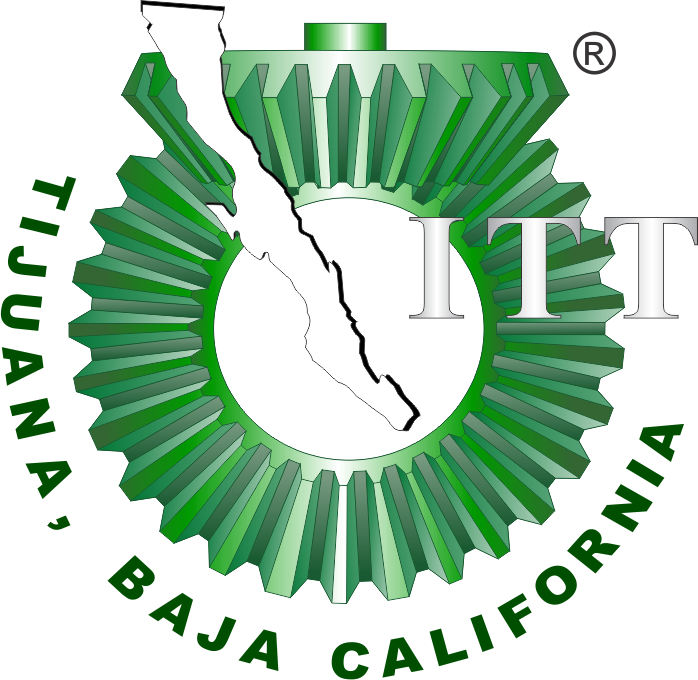

# Proyecto Final: Gemelo Digital

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

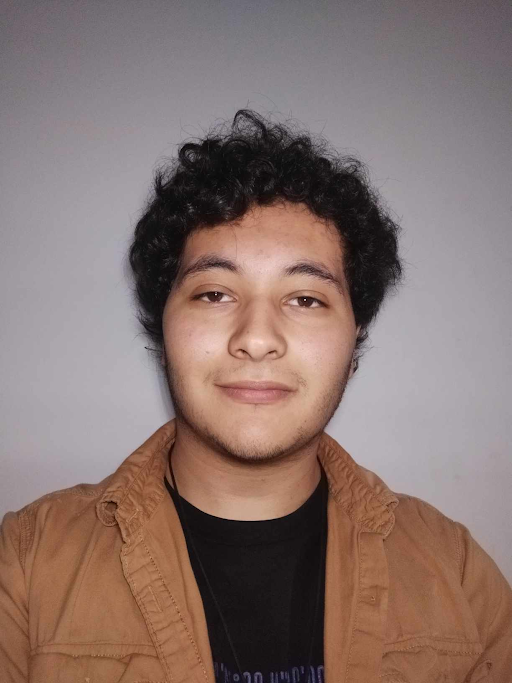

Nombre del alumno: **Hector Andres Fernandez Esquivel**

Número de control: **21212153**

Correo institucional: **l21212153@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Data interpretations

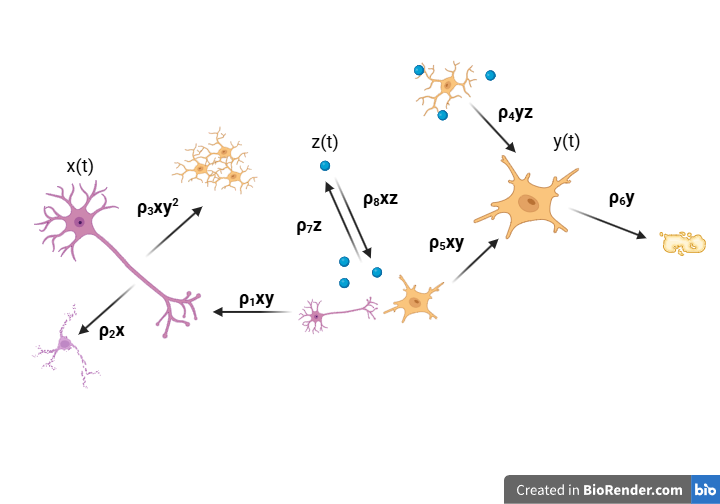

Created in  https://BioRender.com


$$\dot{x} =\rho_1 \textrm{xy}-\rho_2 x-\rho_3 {\textrm{xy}}^2$$


The first equation describes the activity of a neuron, based on it's interaction with a glia $\left(\rho_1 \textrm{xy}\right)$ which are subject to fatigue $\left(-\rho_2 x\right)$, and how this one is inhibited more strongly when there's a higher level of activation $\left(-\rho_3 {\textrm{xy}}^2 \right)$.


$$\dot{y} =\rho_4 \textrm{yz}+\rho_5 \textrm{xy}-\rho_6 y$$


The second equation models glia activation, showing how it's activity increases in response to the neurotransmiter concentration $\left(\rho_4 \textrm{yz}\right)$ as well as it's neural activity $\left(\rho_5 \textrm{xy}\right)$ while it presents a level of natural decay over time $\left(-\rho_6 y\right)$.


$$\dot{z} =\rho_7 z-\rho_8 \textrm{xz}$$


The third equation characterizes the neurotransmitter dynamics, how it can acumulate or undergo basal recycle $\left(\rho_7 z\right)$ which is oftentimes eliminated by a multitude of processes dependent on neural activity $\left(-\rho_8 \textrm{xz}\right)$ making it fall down as long as neural activity persists.

## Simulation data

    Tiempo    x(t)     y(t)     z(t) 
    ______    _____    _____    _____

       0      6.423     1.72    6.319
       7      6.752    2.224    6.228
      14      7.414    2.873    6.043
      21      7.852    3.467    5.832
      28       8.15    4.126    5.682
      35      8.548    4.815    5.456
      42      8.997    5.615     5.13
      49       8.94    6.476    4.892
      56      8.581    7.091    4.615
      63      8.099    7.457    4.188
      70      7.661    7.715    3.911



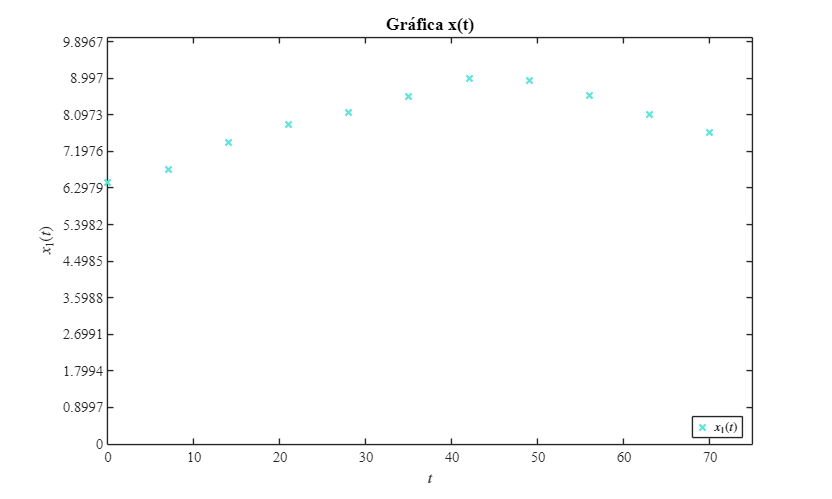

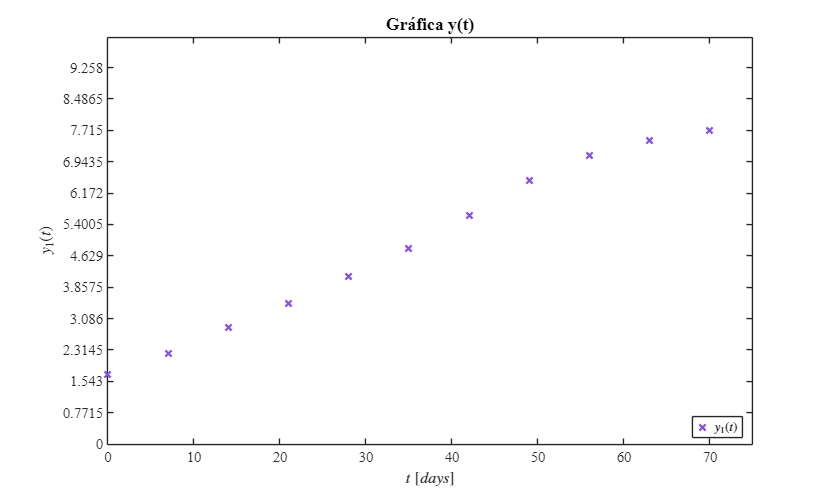

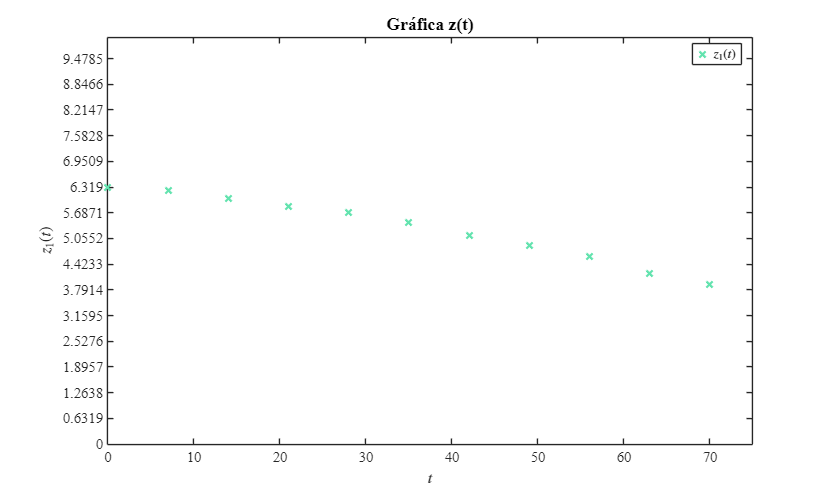

clc; clear; close all; warning('off','all')
sys = readmatrix('data.csv');
to = sys(:,1);
x = sys(:,2);
y = sys(:,3);
z = sys(: ,4);
T1 = array2table([to,x,y,z], 'VariableNames', {'Tiempo', 'x(t)', 'y(t)', 'z(t)'});
disp(T1); plotdata(to,x, y,z);

### Smooth data

xo = smoothdata(x);
yo = smoothdata(y);
zo = smoothdata(z);
T2 = table(to, xo, yo, zo, 'VariableNames', {'Tiempo', 'x_smooth', 'y_smooth', 'z_smooth'});
writetable(T2, 'data_smooth.csv');
disp(T2);

    Tiempo    x_smooth    y_smooth    z_smooth
    ______    ________    ________    ________

       0       6.5875      2.2723      6.1967 
       7        6.863       2.571      6.1055 
      14       7.1102       2.882      6.0208 
      21        7.542       3.501      5.8482 
      28        7.991      4.1792      5.6286 
      35       8.3867      4.8998      5.3984 
      42       8.6587      5.6246       5.155 
      49       8.7665      6.2908      4.8562 
      56       8.6542      6.8708      4.5472 
      63       8.3202      7.1848      4.4015 
      70       8.1137       7.421       4.238 



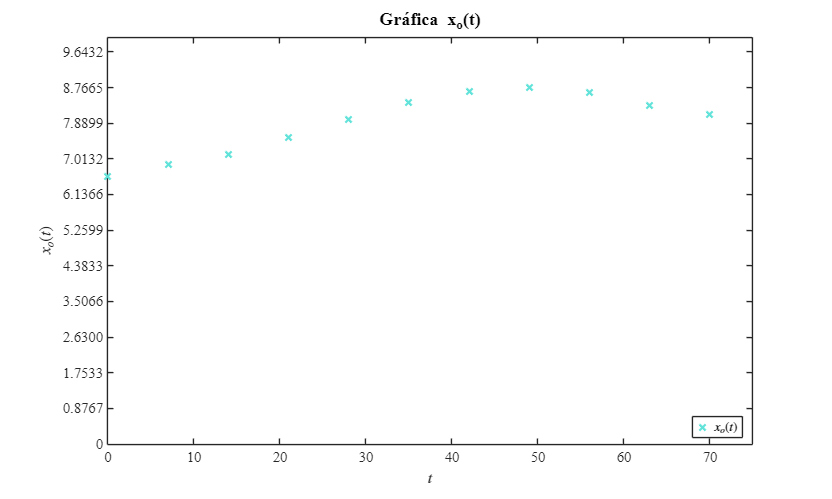

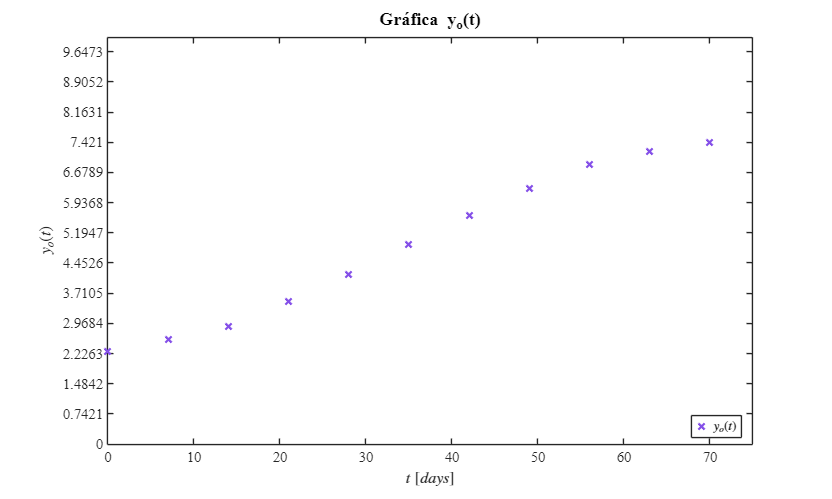

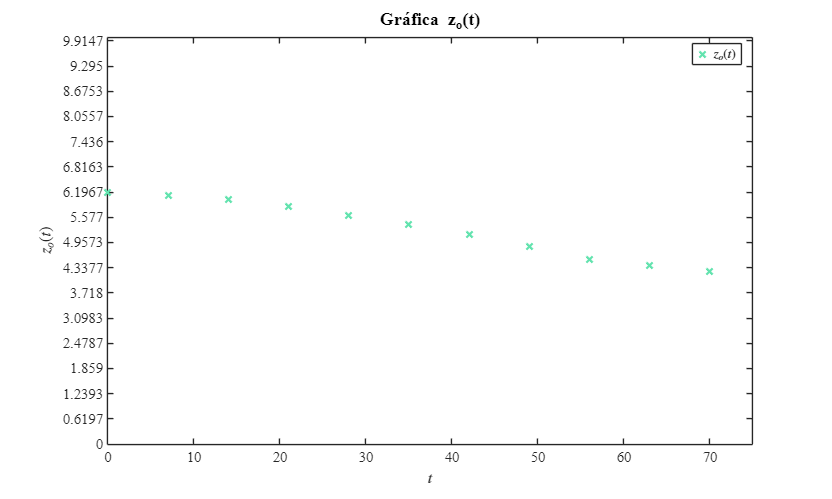

plotEDOSfit(to,xo,yo,zo);

## Nonlinear Algorithms


$$\dot{x} =\rho_1 \textrm{xy}-\rho_2 x-\rho_3 {\textrm{xy}}^2$$



$$\dot{y} =\rho_4 \textrm{yz}+\rho_5 \textrm{xy}-\rho_6 y$$



$$\dot{z} =\rho_7 z-\rho_8 \textrm{xz}$$



Sample size (n): 11
Parameters to be estimated (pars): 8
Degrees of freedom: 25
Significance level (alpha): 0.05
t-Student value: 2.0595
R-squared: 0.99919
Corrected AIC (n/pars < 40): -80.4396

    Parameters     Estimate         SE           MoE                  CI95                pvalue  
    __________    __________    __________    __________    ________________________    __________

        p1         0.0069597     0.0010741     0.0022121     0.0047477     0.0091718    8.7138e-07
        p2         0.0051957     0.0023098     0.0047572    0.00043851     0.0099528      0.033541
        p3        0.00096592    0.00011209    0.00023086    0.00073506     0.0011968    5.9035e-09
        p4            0.0165     0.0011757     0.0024215      0.014079      0.018921    2.3369e-13
     

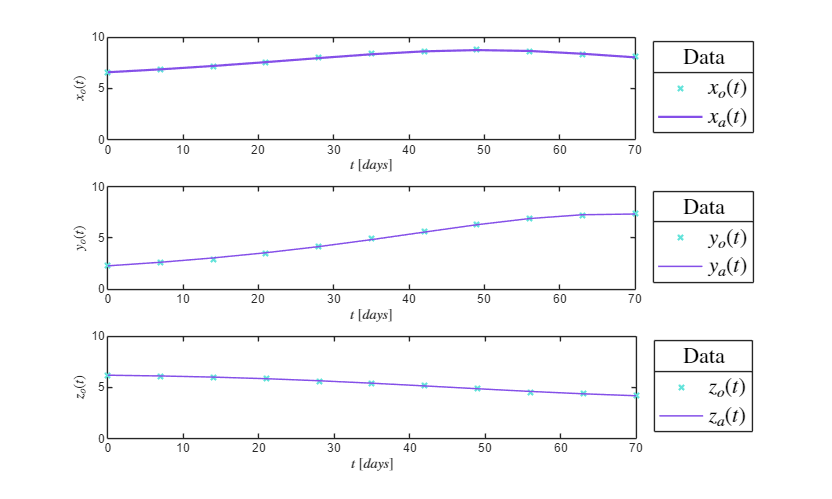

P0 = [0.00696, 0.005197, 0.000965, 0.0165, 0.008033, 0.13523, 0.019183, 0.003106];
[mdl,xa,ya,za] = Varied(to,xo,yo,zo,P0); plotreqs(to,[xo,xa],[yo,ya],[zo,za])

## Equilibrium Points and Jacobian matrix

clear; close all; clc;
syms x y z rho1 rho2 rho3 rho4 rho5 rho6 rho7 rho8
dx = rho1*x*y - rho2*x - rho3*x*y^2;
dy = rho4*y*z + rho5*x*y - rho6*y;
dz = rho7*z - rho8*x*z;
J = jacobian([dx,dy,dz],[x,y,z]);
fprintf('Jacobian matrix of the Lotka-Volterra system:'); disp(J)

Jacobian matrix of the Lotka-Volterra system:

$$\left(\begin{array}{ccc} -\rho_{3}\,y^{2}+\rho_{1}\,y-\rho_{2} & \rho_{1}\,x-2\,\rho_{3}\,x\,y & 0\\ \rho_{5}\,y & \rho_{5}\,x-\rho_{6}+\rho_{4}\,z & \rho_{4}\,y\\ -\rho_{8}\,z & 0 & \rho_{7}-\rho_{8}\,x \end{array}\right)$$

dx = rho1*x*y - rho2*x - rho3*x*y^2 == 0;
dy = rho4*y*z + rho5*x*y - rho6*y == 0;
dz = rho7*z - rho8*x*z == 0;
edos = solve([dx,dy,dz],[x,y,z]);
fprintf(['The Lotka-Volterra system has ',num2str(length(edos.x)),' equilibrium points.'])

The Lotka-Volterra system has 5 equilibrium points.

X0 = edos.x(1); Y0 = edos.y(1); Z0 = edos.z(1);
X1 = edos.x(2); Y1 = edos.y(2); Z1 = edos.z(2);
X2 = edos.x(3); Y2 = edos.y(3); Z2 = edos.z(3);
X3 = edos.x(4); Y3 = edos.y(4); Z3 = edos.z(4);
X4 = edos.x(5); Y4 = edos.y(5); Z4 = edos.z(5);
syms x0 y0 z0 x1 y1 z1 x2 y2 z2 x3 y3 z3 x4 y4 z4
fprintf('Equilibrium points of the Lotka-Volterra system:'); disp([x0,y0,z0,X0,Y0,Z0]); disp([x1,y1,z1,X1,Y1,Z1]); disp([x2,y2,z2,X2,Y2,Z2]); disp([x3,y3,z3,X3,Y3,Z3]); disp([x4,y4,z4,X4,Y4,Z4]);

Equilibrium points of the Lotka-Volterra system:

$$\left(\begin{array}{cccccc} x_{0} & y_{0} & z_{0} & 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccccc} x_{1} & y_{1} & z_{1} & \frac{\rho_{7}}{\rho_{8}} & \frac{\rho_{1}+\sqrt{{\rho_{1}}^{2}-4\,\rho_{2}\,\rho_{3}}}{2\,\rho_{3}} & -\frac{\rho_{5}\,\rho_{7}-\rho_{6}\,\rho_{8}}{\rho_{4}\,\rho_{8}} \end{array}\right)$$

$$\left(\begin{array}{cccccc} x_{2} & y_{2} & z_{2} & \frac{\rho_{6}}{\rho_{5}} & \frac{\rho_{1}+\sqrt{{\rho_{1}}^{2}-4\,\rho_{2}\,\rho_{3}}}{2\,\rho_{3}} & 0 \end{array}\right)$$

$$\left(\begin{array}{cccccc} x_{3} & y_{3} & z_{3} & \frac{\rho_{7}}{\rho_{8}} & \frac{\rho_{1}-\sqrt{{\rho_{1}}^{2}-4\,\rho_{2}\,\rho_{3}}}{2\,\rho_{3}} & -\frac{\rho_{5}\,\rho_{7}-\rho_{6}\,\rho_{8}}{\rho_{4}\,\rho_{8}} \end{array}\right)$$

$$\left(\begin{array}{cccccc} x_{4} & y_{4} & z_{4} & \frac{\rho_{6}}{\rho_{5}} & \frac{\rho_{1}-\sqrt{{\rho_{1}}^{2}-4\,\rho_{2}\,\rho_{3}}}{2\,\rho_{3}} & 0 \end{array}\right)$$

clear rho1 rho2 rho3 rho4 rho5 rho6 rho7 rho8
%p = [0.00696, 0.005197, 0.000965, 0.0165, 0.008033, 0.13523, 0.019183, 0.003106];
rho1 = 0.00696; rho2 = 0.005197; rho3 = 0.000965; rho4 = 0.0165; 
rho5 = 0.008033; rho6 = 0.13523; rho7 = 0.019183; rho8 = 0.003106;
eq1 = '(x0,y0,z0) = (0,0,0)';
eq2 = ['(x1,y1,z1) = (' num2str(rho7/rho8) ',' num2str(rho1 + sqrt(rho1^2 - 4*rho2*rho3)/(2*rho3)) ',' num2str(-(rho5*rho7 - rho6*rho8)/(rho4*rho8)) ')']; 
eq3 = ['(x2,y2,z2) = (' num2str(rho6/rho5) ',' num2str(rho1 + sqrt(rho1^2 - 4*rho2*rho3)/(2*rho3)) ',0)'];
eq4 = ['(x3,y3,z3) = (' num2str(rho7/rho8) ',' num2str(rho1 - sqrt(rho1^2 - 4*rho2*rho3)/(2*rho3)) ',' num2str(-(rho5*rho7 - rho6*rho8)/(rho4*rho8)) ')']; 
eq5 = ['(x4,y4,z4) = (' num2str(rho6/rho5) ',' num2str(rho1 - sqrt(rho1^2 - 4*rho2*rho3)/(2*rho3)) ',0)'];
disp(eq1); disp(eq2); disp(eq3); disp(eq4); disp(eq5)

(x0,y0,z0) = (0,0,0)
(x1,y1,z1) = (6.1761,2.7673,5.1889)
(x2,y2,z2) = (16.8343,2.7673,0)
(x3,y3,z3) = (6.1761,-2.7534,5.1889)
(x4,y4,z4) = (16.8343,-2.7534,0)


### Local stability

clear; close all; clc;
syms x y z 
rho1 = 0.00696; rho2 = 0.005197; rho3 = 0.000965; rho4 = 0.0165; 
rho5 = 0.008033; rho6 = 0.13523; rho7 = 0.019183; rho8 = 0.003106;
dx = rho1*x*y - rho2*x - rho3*x*y^2 == 0;
dy = rho4*y*z + rho5*x*y - rho6*y == 0;
dz = rho7*z - rho8*x*z == 0;
edos = solve([dx,dy,dz],[x,y,z]);
%fprintf(['The Lotka-Volterra system has ',num2str(length(edos.x)),' equilibrium points.'])
x0 = double(edos.x(1)); y0 = double(edos.y(1)); z0 = double(edos.z(1));
x1 = double(edos.x(2)); y1 = double(edos.y(2)); z1 = double(edos.z(2));
x2 = double(edos.x(3)); y2 = double(edos.y(3)); z2 = double(edos.z(3));
x3 = double(edos.x(4)); y3 = double(edos.y(4)); z3 = double(edos.z(4));
x4 = double(edos.x(5)); y4 = double(edos.y(5)); z4 = double(edos.z(5));
clear x y z
x = [x0; x1; x2; x3; x4]; y = [y0; y1; y2; y3; y4]; z = [z0; z1; z2; z3; z4];
var = {'(x0,y0,z0)'; '(x1,y1,z1)'; '(x2,y2,z2)'; '(x3,y3,z3)'; '(x4,y4,z4)'};
Equilibria = table(x,y,z,'RowNames',var);
Equilibria.Properties.VariableNames = {'xe','ye','ze'};
fprintf('Equilibrium points of the Lotka-Volterra system:\n'); disp(Equilibria)

Equilibrium points of the Lotka-Volterra system:
                    xe        ye         ze  
                  ______    _______    ______

    (x0,y0,z0)         0          0         0
    (x1,y1,z1)    6.1761    0.84591    5.1889
    (x2,y2,z2)    6.1761     6.3665    5.1889
    (x3,y3,z3)    16.834    0.84591         0
    (x4,y4,z4)    16.834     6.3665         0



L = zeros(length(x),3);
for i = 1:length(x)
    J = [- rho3*y(i)^2 + rho1*y(i) - rho2, rho1*x(i) - 2*rho3*x(i)*y(i), 0; 
         rho5*y(i), rho5*x(i) - rho6 + rho4*z(i), rho4*y(i); 
         -rho8*z(i), 0, rho7 - rho8*x(i)];
    L(i,:) = double(eig(J));
end
L1 = L(:,1); L2 = L(:,2); L3 = L(:,3);
var = {'(x0,y0,z0)'; '(x1,y1,z1)'; '(x2,y2,z2)'; '(x3,y3,z3)'; '(x4,y4,z4)'};
Lambdas = table(L1,L2,L3,'RowNames',var);
disp('Eigenvalues of the Jacobian matrix evaluated at each equilibrium point:'); disp(Lambdas)

Eigenvalues of the Jacobian matrix evaluated at each equilibrium point:
                          L1                     L2                     L3         
                  ___________________    ___________________    ___________________

    (x0,y0,z0)     -0.13523+0i           -0.005197+0i            0.019183+0i       
    (x1,y1,z1)    -0.023273+0i            0.011636+0.013514i     0.011636-0.013514i
    (x2,y2,z2)    -0.012217+0.046157i    -0.012217-0.046157i     0.024435+0i       
    (x3,y3,z3)     0.024686+0i           -0.024686+0i           -0.033104+0i       
    (x4,y4,z4)            0+0.067724i            0-0.067724i    -0.033104+0i       



## Algorithm in 2t

clc; clear; close all;
sys = readmatrix('data_smooth.csv');
to = sys(:,1);
xo = sys(:,2);
yo = sys(:,3);
zo = sys(:,4);
T2 = array2table([to,xo,yo,zo], 'VariableNames', {'Tiempo', 'xo(t)', 'yo(t)', 'zo(t)'});
disp(T2);

    Tiempo    xo(t)     yo(t)     zo(t) 
    ______    ______    ______    ______

       0      6.5875    2.2723    6.1967
       7       6.863     2.571    6.1055
      14      7.1102     2.882    6.0208
      21       7.542     3.501    5.8482
      28       7.991    4.1792    5.6286
      35      8.3867    4.8998    5.3984
      42      8.6587    5.6246     5.155
      49      8.7665    6.2908    4.8562
      56      8.6542    6.8708    4.5472
      63      8.3202    7.1848    4.4015
      70      8.1137     7.421     4.238



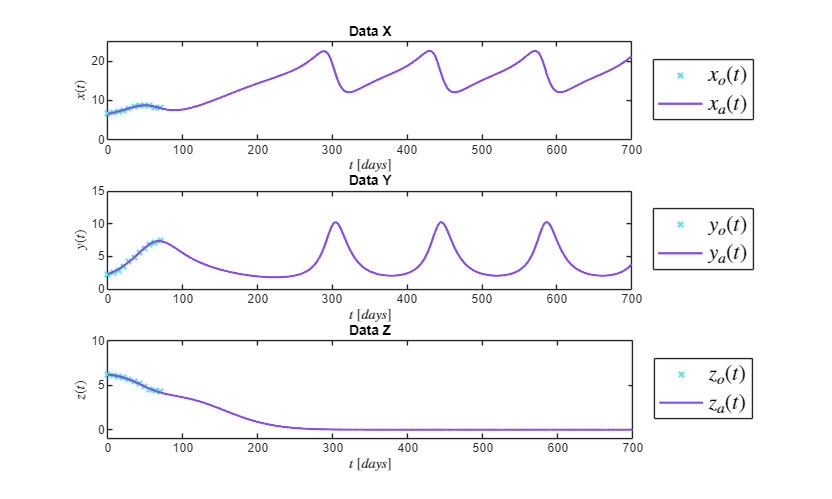

tend = 10*max(to); dt = 1E-2;
p = [0.00696, 0.005197, 0.000965, 0.0165, 0.008033, 0.13523, 0.019183, 0.003106];
[t,x,y,z] = Variente(xo(1),yo(1),zo(1),dt,tend,p); plotgreqs(to, xo, yo, zo, t, x, y, z)

## Normalized plot

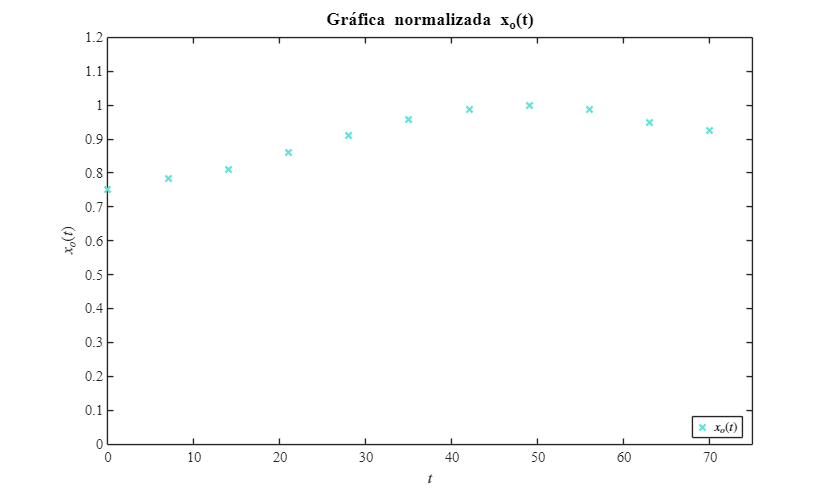

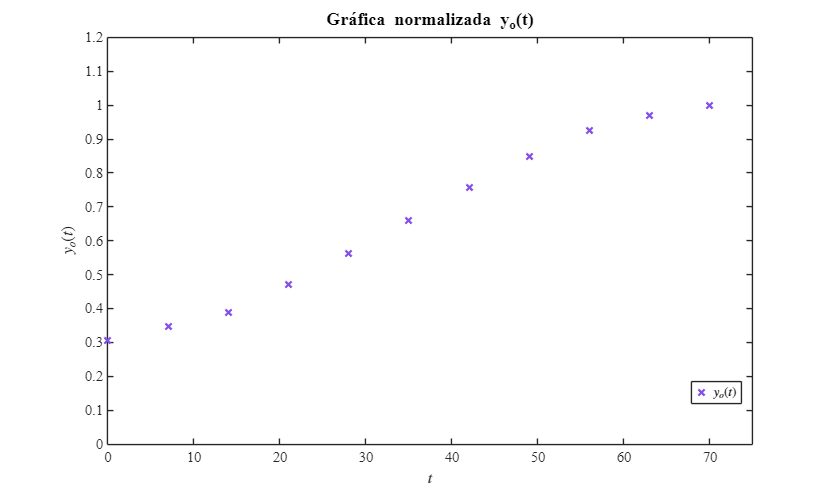

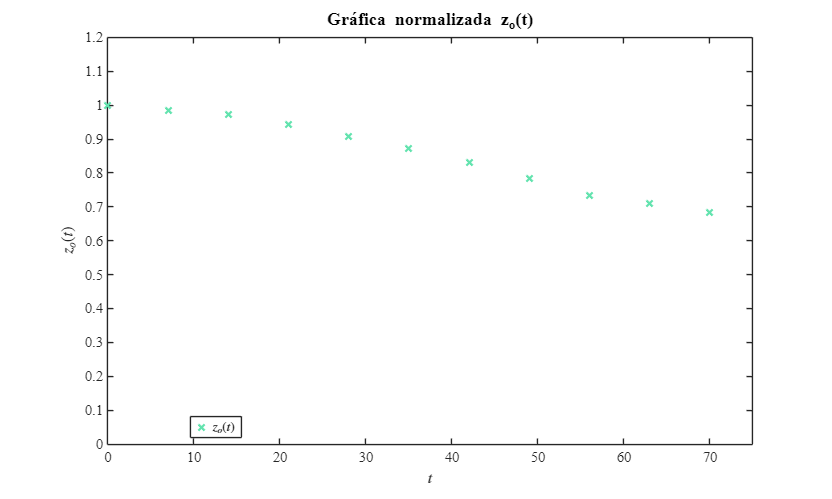

plotnorm(to,xo,yo,zo)

## Conclusions

This proyect has allowed us to explore the behaviour of a set of biological variables and analyze their evolution over time. Through this interpretation, we designed a model that can simulate its dynamics in a way while also determining the statistical significance and local stability of the model. Overall the model captured a system where there exists oscillations inside of variables $x\left(t\right)$ and $y\left(t\right)$ meanwhile $z\left(t\right)$ shows a convergence to $0$ where $t\to \infty$.

## Functions

### Plotting

function plotdata(t,x,y,z)

    c1 = [98,227,218]/255;
    c2 = [132,79,232]/255; 
    c3 = [98,227,174]/255;

    % Gráfica para x(t)
    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [2, 2, 20, 12])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    hold on; box on; grid off;
    plot(t, x, 'x', 'LineWidth', 1.5, 'Color', c1, 'DisplayName', '$x_1(t)$')
    xlabel('$t$', 'Interpreter', 'latex')
    ylabel('$x_1(t)$', 'Interpreter', 'latex')
    xlim([0 max(t)+5]); xticks(0:10:max(t)+5)
    ylim([0 10]); yticks(0:max(x)/10:10)
    title('Gráfica x(t)', 'FontSize', 12)
    legend('Interpreter', 'latex', 'Location', 'best')

    % Gráfica para y(t)
    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [24, 2, 20, 12])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    hold on; box on; grid off;
    plot(t, y, 'x', 'LineWidth', 1.5, 'Color', c2, 'DisplayName', '$y_1(t)$')
    xlabel('$t$ $[days]$', 'Interpreter', 'latex')
    ylabel('$y_1(t)$', 'Interpreter', 'latex')
    xlim([min(t), max(t)+5]); xticks(0:10:max(t)+5)
    ylim([0 10]); yticks(0:max(y)/10:10)
    title('Gráfica y(t)', 'FontSize', 12)
    legend('Interpreter', 'latex', 'Location', 'best')

    % Gráfica para z(t)
    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [46, 2, 20, 12])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    hold on; box on; grid off;
    plot(t, z, 'x', 'LineWidth', 1.5, 'Color', c3, 'DisplayName', '$z_1(t)$')
    xlabel('$t$', 'Interpreter', 'latex')
    ylabel('$z_1(t)$', 'Interpreter', 'latex')
    xlim([0 max(t)+5]); xticks(0:10:max(t)+5)
    ylim([0 10]); yticks(0:max(z)/10:10)
    title('Gráfica z(t)', 'FontSize', 12)
    legend('Interpreter', 'latex', 'Location', 'best')
end

function plotEDOSfit(t,x,y,z)

    c1 = [98,227,218]/255;
    c2 = [132,79,232]/255; 
    c3 = [98,227,174]/255;

    % Gráfica para x(t)
    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [2, 2, 20, 12])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    hold on; box on; grid off;
    plot(t, x, 'x', 'LineWidth', 1.5, 'Color', c1, 'DisplayName', '$x_o(t)$')
    xlabel('$t$', 'Interpreter', 'latex')
    ylabel('$x_o(t)$', 'Interpreter', 'latex')
    xlim([0 max(t)+5]); xticks(0:10:max(t)+5)
    ylim([0 10]); yticks(0:max(x)/10:10)
    title('Gráfica x_o(t)', 'FontSize', 12)
    legend('Interpreter', 'latex', 'Location', 'best')

    % Gráfica para y(t)
    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [24, 2, 20, 12])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    hold on; box on; grid off;
    plot(t, y, 'x', 'LineWidth', 1.5, 'Color', c2, 'DisplayName', '$y_o(t)$')
    xlabel('$t$ $[days]$', 'Interpreter', 'latex')
    ylabel('$y_o(t)$', 'Interpreter', 'latex')
    xlim([min(t), max(t)+5]); xticks(0:10:max(t)+5)
    ylim([0 10]); yticks(0:max(y)/10:10)
    title('Gráfica y_o(t)', 'FontSize', 12)
    legend('Interpreter', 'latex', 'Location', 'best')

    % Gráfica para z(t)
    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [46, 2, 20, 12])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    hold on; box on; grid off;
    plot(t, z, 'x', 'LineWidth', 1.5, 'Color', c3, 'DisplayName', '$z_o(t)$')
    xlabel('$t$', 'Interpreter', 'latex')
    ylabel('$z_o(t)$', 'Interpreter', 'latex')
    xlim([0 max(t)+5]); xticks(0:10:max(t)+5)
    ylim([0 10]); yticks(0:max(z)/10:10)
    title('Gráfica z_o(t)', 'FontSize', 12)
    legend('Interpreter', 'latex', 'Location', 'best')
end

function plotreqs(t,x,y,z)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    set(gca,'FontName','Times New Roman')
    fontsize(12,'points')
    c1 = [98,227,218]/255;
    c2 = [132,79,232]/255;

    subplot(3,1,1)
    hold on; box on; grid off;
    plot(t,x(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',c1)
    plot(t,x(:,2),'-','LineWidth',1.5,'Color',c2)
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$x_o(t)$','Interpreter','latex')
    L = legend ('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','latex','FontSize',15,'Location','EastOutside','Box','On')
    title(L,'Data')
    xlim([min(t) max(t)])
    ylim([0 10])

    subplot(3,1,2)
    hold on; box on; grid off;
    plot(t,y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',c1)
    plot(t,y(:,2),'-','LineWidth',1,'Color',c2)
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$y_o(t)$','Interpreter','latex')
    L = legend ('$y_o(t)$','$y_a(t)$');
    set(L,'Interpreter','latex','FontSize',15,'Location','EastOutside','Box','On')
    title(L,'Data')
    xlim([min(t) max(t)])
    ylim([0 10])

    subplot(3,1,3)
    hold on; box on; grid off;
    plot(t,z(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',c1)
    plot(t,z(:,2),'-','LineWidth',1,'Color',c2)
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$z_o(t)$','Interpreter','latex')
    L = legend ('$z_o(t)$','$z_a(t)$');
    set(L,'Interpreter','latex','FontSize',15,'Location','EastOutside','Box','On')
    title(L,'Data')
    xlim([min(t) max(t)])
    ylim([0 10])
end

function plotgreqs(to, xo, yo, zo, t, xa, ya, za)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    set(gca,'FontName','Times New Roman')
    fontsize(12,'points')
    
    c1 = [98,227,218]/255;   
    c2 = [132,79,232]/255; 

    subplot(3,1,1)
    hold on; box on; grid off;
    plot(to, xo, 'x', 'MarkerSize', 5, 'LineWidth', 1.5, 'Color', c1)           
    plot(t, xa, '-', 'LineWidth', 1.5, 'Color', c2)                       
    xlabel('$t$ $[days]$', 'Interpreter', 'latex')
    ylabel('$x(t)$', 'Interpreter', 'latex')
    legend({'$x_o(t)$', '$x_a(t)$'}, 'Interpreter', 'latex', 'FontSize', 15, ...
           'Location', 'EastOutside', 'Box', 'on')
    title('Data X')
    xlim([min(t) max(t)])
    ylim([0 25])

    subplot(3,1,2)
    hold on; box on; grid off;
    plot(to, yo, 'x', 'MarkerSize', 5, 'LineWidth', 1.5, 'Color', c1)
    plot(t, ya, '-', 'LineWidth', 1.5, 'Color', c2)
    xlabel('$t$ $[days]$', 'Interpreter', 'latex')
    ylabel('$y(t)$', 'Interpreter', 'latex')
    legend({'$y_o(t)$', '$y_a(t)$'}, 'Interpreter', 'latex', 'FontSize', 15, ...
           'Location', 'EastOutside', 'Box', 'on')
    title('Data Y')
    xlim([min(t) max(t)])
    ylim([0 15])

    subplot(3,1,3)
    hold on; box on; grid off;
    plot(to, zo, 'x', 'MarkerSize', 5, 'LineWidth', 1.5, 'Color', c1)
    plot(t, za, '-', 'LineWidth', 1.5, 'Color', c2)
    xlabel('$t$ $[days]$', 'Interpreter', 'latex')
    ylabel('$z(t)$', 'Interpreter', 'latex')
    legend({'$z_o(t)$', '$z_a(t)$'}, 'Interpreter', 'latex', 'FontSize', 15, ...
           'Location', 'EastOutside', 'Box', 'on')
    title('Data Z')
    xlim([min(t) max(t)])
    ylim([-1 10])
end

function plotnorm(t,x,y,z)

    c1 = [98,227,218]/255;
    c2 = [132,79,232]/255; 
    c3 = [98,227,174]/255;

    x_norm = x / max(x);
    y_norm = y / max(y);
    z_norm = z / max(z);

    % Gráfica para x(t)
    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [2, 2, 20, 12])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    hold on; box on; grid off;
    plot(t, x_norm, 'x', 'LineWidth', 1.5, 'Color', c1, 'DisplayName', '$x_o(t)$')
    xlabel('$t$', 'Interpreter', 'latex')
    ylabel('$x_o(t)$', 'Interpreter', 'latex')
    xlim([0 max(t)+5]); xticks(0:10:max(t)+5)
    ylim([0 1.2]); yticks(0:0.1:1.2)
    title('Gráfica normalizada x_o(t)', 'FontSize', 12)
    legend('Interpreter', 'latex', 'Location', 'best')

    % Gráfica para y(t)
    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [24, 2, 20, 12])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    hold on; box on; grid off;
    plot(t, y_norm, 'x', 'LineWidth', 1.5, 'Color', c2, 'DisplayName', '$y_o(t)$')
    xlabel('$t$', 'Interpreter', 'latex')
    ylabel('$y_o(t)$', 'Interpreter', 'latex')
    xlim([0 max(t)+5]); xticks(0:10:max(t)+5)
    ylim([0 1.2]); yticks(0:0.1:1.2)
    title('Gráfica normalizada y_o(t)', 'FontSize', 12)
    legend('Interpreter', 'latex', 'Location', 'best')

    % Gráfica para z(t)
    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [46, 2, 20, 12])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10)
    hold on; box on; grid off;
    plot(t, z_norm, 'x', 'LineWidth', 1.5, 'Color', c3, 'DisplayName', '$z_o(t)$')
    xlabel('$t$', 'Interpreter', 'latex')
    ylabel('$z_o(t)$', 'Interpreter', 'latex')
    xlim([0 max(t)+5]); xticks(0:10:max(t)+5)
    ylim([0 1.2]); yticks(0:0.1:1.2)
    title('Gráfica normalizada z_o(t)', 'FontSize', 12)
    legend('Interpreter', 'latex', 'Location', 'best')

end

### Nonlinear Modelling

function [mdl,xa,ya,za] = Varied(to,xo,yo,zo,P0)
    x0 = xo(1); y0 = yo(1); z0 = zo(1);
    to = [to;to;to];
    fo = [xo;yo;zo];

    function fi = model(p,t)
        dt = 1E-2;
        t = reshape (t,[],3); t = t(:,1);
        time = (0:dt:max(t));
        n = round(max(t)/dt);
        x = zeros(n+1,1); x(1) = x0;
        y = zeros(n+1,1); y(1) = y0;
        z = zeros(n+1,1); z(1) = z0;

        for i = 1:n
            [fx,fy,fz] = f(x(i),y(i),z(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            zn = z(i) + fz*dt;
            [fxn,fyn,fzn] = f(xn,yn,zn);

            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
            z(i+1) = z(i) + (fz + fzn)*dt/2;
        end

        function [dx,dy,dz] = f(x,y,z)
            dx = p(1)*x*y - p(2)*x - p(3)*x*y^2;
            dy = p(4)*y*z + p(5)*x*y - p(6)*y;
            dz = p(7)*z - p(8)*x*z;
        end 
        
        xi = interp1(time,x,t);
        yi = interp1(time,y,t);
        zi = interp1(time,z,t);

        fi = [xi;yi;zi];
    end

    mdl = fitnlm(to,fo,@model,P0);

    fa = mdl.Fitted;
    fn = reshape(fa,[],3);
    xa = fn(:,1); ya = fn(:,2); za = fn(:,3);

    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = ['p1';'p2';'p3';'p4';'p5';'p6';'p7';'p8';];
    Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);

    fprintf(['\nSample size (n): ', num2str(numel(xo))]) 
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(P0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student value: ', num2str(tval)])
    fprintf(['\nR-squared: ', num2str(mdl.Rsquared.Ordinary)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])
    disp(Results)
end

function [t,x,y,z] = Variente(xo,yo,zo,dt,tend,p)
    t = (0:dt:tend)';
    N = length(t);
    x = zeros(N,1); x(1) = xo;
    y = zeros(N,1); y(1) = yo;
    z = zeros(N,1); z(1) = zo;

    for i = 1:N-1
        [fx, fy, fz] = f(x(i), y(i), z(i), p);
        xn = x(i) + fx * dt;
        yn = y(i) + fy * dt;
        zn = z(i) + fz * dt;
        
        [fxn, fyn, fzn] = f(xn, yn, zn, p);
        x(i+1) = x(i) + (fx + fxn) * dt / 2;
        y(i+1) = y(i) + (fy + fyn) * dt / 2;
        z(i+1) = z(i) + (fz + fzn) * dt / 2;
    end
end

 function [dx, dy, dz] = f(x, y, z, p)
    dx = p(1)*x*y - p(2)*x - p(3)*x*y^2;
    dy = p(4)*y*z + p(5)*x*y - p(6)*y;
    dz = p(7)*z - p(8)*x*z;
 end

## Bibliografia

[1] Paul. A. Valle, Syllabus de Biomatemáticas para la asignatura de Gemelos Digitales, Tecnológico Nacional de México/IT Tijuana, Tijuana, B.C., México, 2025. Permalink: [https://www.dropbox.com/s/6yf9afxzih9y458/Biomatematicas.pdf](https://www.dropbox.com/s/6yf9afxzih9y458/Biomatematicas.pdf)